# Progetto SMS2 processo stocastico

clc
clear
clearvars 
warning ('off', 'all')
addpath('.\isstationary')
addpath('.\TSAF')

% carico dataset
dataset = readtable('AirQualityUCI.xlsx');

% replace values -200 with NaN value
dataset = standardizeMissing(dataset,-200);

% set dataset to analyze
data = dataset(:,{'Date', 'Time', 'CO_GT_', 'PT08_S1_CO_', 'NMHC_GT_', 'C6H6_GT_', 'PT08_S2_NMHC_', 'NOx_GT_', 'PT08_S3_NOx_', 'NO2_GT_',  'PT08_S4_NO2_',  'PT08_S5_O3_', 'T', 'RH', 'AH'});
data.Properties.VariableNames = {'Date', 'Time', 'CO', 'S1.CO', 'NMHC', 'C6H6', 'S2.NMHC', 'NOx', 'S3.NOx', 'NO2', 'S4.NO2', 'S5.O3', 'T', 'RH', 'AH'};
sensor_data = data(:,{'S1.CO','S2.NMHC', 'S3.NOx', 'S4.NO2', 'S5.O3', 'T', 'RH', 'AH'});


sum(isoutlier(sensor_data.("S1.CO")))

ans = 101

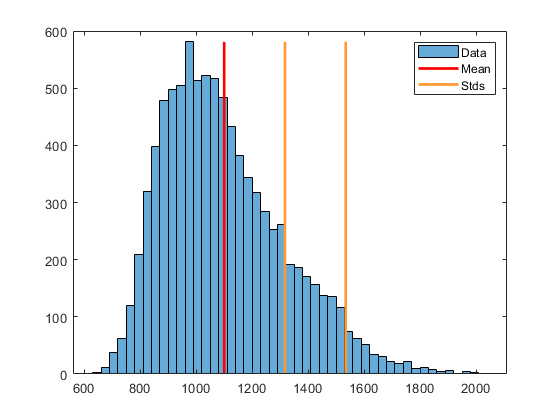

% Outlier
y = sensor_data.("S1.CO");
h = histogram(y);
N = max(h.Values);
mu = nanmean(y);
sigma = nanstd(y);


% plot(t,residui,t(TF),residui(TF),'x')
% yline(+2*std(residui), 'Color', 'red')
% yline(-2*std(residui), 'Color', 'red')
% yline(+3*std(residui), 'Color', 'blue')
% yline(-3*std(residui), 'Color', 'blue')
% legend('Data','Outlier', '±2σ', '±3σ')


hold on
plot([mu mu],[0 N],'r','LineWidth',2) % Mean
X = repmat(mu+(1:2)*sigma,2,1);
Y = repmat([0;N],1,2);
plot(X,Y,'Color',[255 153 51]./255,'LineWidth',2) % Standard deviations
legend('Data','Mean','Stds')
hold off

outliers = (y - mu) > 2*sigma;
y(outliers) = NaN; % Add NaN values
sum(isnan(y))

ans = 716

sensor_data.("S1.CO") = y

sensor_data = 9357×8 table
    S1.CO     S2.NMHC    S3.NOx    S4.NO2    S5.O3       T         RH        AH   
    ______    _______    ______    ______    ______    ______    ______    _______

      1360    1045.5     1056.3      1692    1267.5      13.6    48.875    0.75775
    1292.3    954.75     1173.8    1558.8    972.25      13.3      47.7    0.72549
      1402    939.25       1140    1554.5      1074      11.9    53.975    0.75024
    1375.5    948.25       1092    1583.8    1203.3        11        60    0.78671
    1272.3     835.5       1205      1490      1110     11.15    59.575    0.78879
      1197    750.25     1336.5      1393    949.25    11.175    59.175    0.78477
      1185     689.5     1461.8    1

sum(isnan(sensor_data.("S1.CO")))

ans = 716

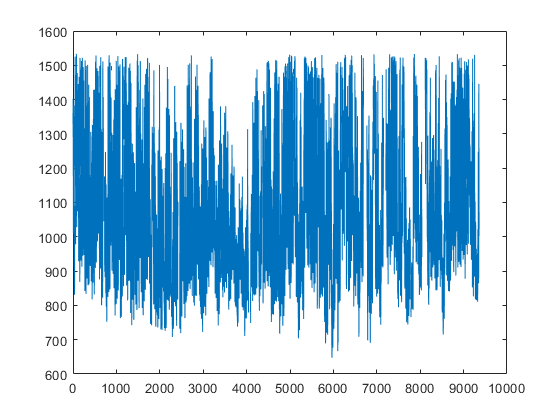

plot(y)

% Applying KNN method to NAN values
c3NaNCount = sum(isnan(sensor_data{:,:}))

c3NaNCount =    716   366   366   366   366   366   366   366


sensor_data = fillmissing(sensor_data, 'linear')

sensor_data = 9357×8 table
    S1.CO     S2.NMHC    S3.NOx    S4.NO2    S5.O3       T         RH        AH   
    ______    _______    ______    ______    ______    ______    ______    _______

      1360    1045.5     1056.3      1692    1267.5      13.6    48.875    0.75775
    1292.3    954.75     1173.8    1558.8    972.25      13.3      47.7    0.72549
      1402    939.25       1140    1554.5      1074      11.9    53.975    0.75024
    1375.5    948.25       1092    1583.8    1203.3        11        60    0.78671
    1272.3     835.5       1205      1490      1110     11.15    59.575    0.78879
      1197    750.25     1336.5      1393    949.25    11.175    59.175    0.78477
      1185     689.5     1461.8    1

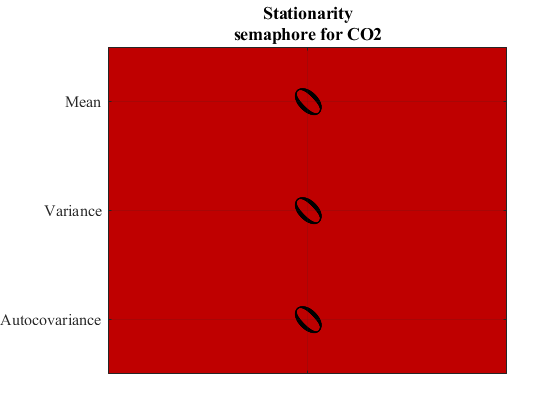

% test stazionarietà
[~, mean_stat_flag1, var_stat_flag1, covar_stat_flag1] = isstationary(sensor_data.("S1.CO"));
figure(1)
matvisual([mean_stat_flag1; var_stat_flag1; covar_stat_flag1], 'annotation')
set(gca, 'FontName', 'Times New Roman')
title(['Stationarity' newline 'semaphore for CO2'])
xlabel([])
ylabel([])
set(gca, 'XTickLabel', [])
set(gca, 'YTickLabel', {'Mean', 'Variance', 'Autocovariance'})
colormap([0.75, 0, 0; 0, 0.75, 0])

% Removing trend from S1.CO
y = sensor_data.('S1.CO')

y = 	1.0e+03 *

    1.3600
    1.2922
    1.4020
    1.3755
    1.2723
    1.1970
    1.1850
    1.1362
    1.0940
    1.0097


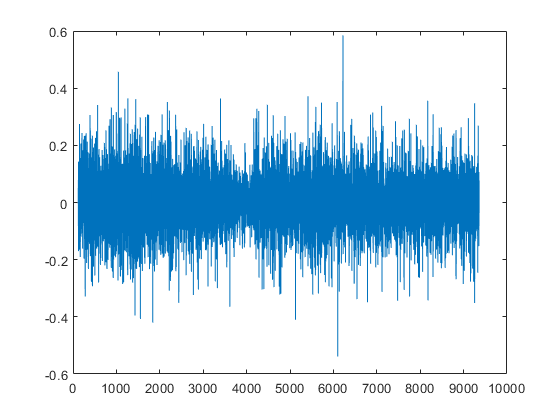

%% Log Transformation
% Log Transformation of S1_CO to remove an exponential trend
y_log = log(y);

%% Detrend
% Remove linear trend from S1_COLog
validIdx = find(~isnan(y_log));
S1_COLogDetrend = [nan(validIdx(1)-1,1), detrend(y_log(validIdx)), nan(length(y_log)-validIdx(end),1)];

%% First Order Difference
% Perform a first order difference on time series S1_COLogDetrend
S1_COLogDetrendDiff = [NaN; diff(S1_COLogDetrend)];

%% Seasonal Difference
% Perform a seasonal difference on time series S1_COLogDetrendDiff with periodicity 120
LagPoly = LagOp({1,-1},'Lags',[0,120]);
y_final = [nan(120,1); filter(LagPoly,S1_COLogDetrendDiff)];
plot(y_final) 

% test stazionarietà
y_final = rmmissing(y_final)

y_final =     0.0502
   -0.0825
    0.0181
    0.0771
   -0.1703
    0.1429
   -0.1515
   -0.0663
    0.0393
    0.0113


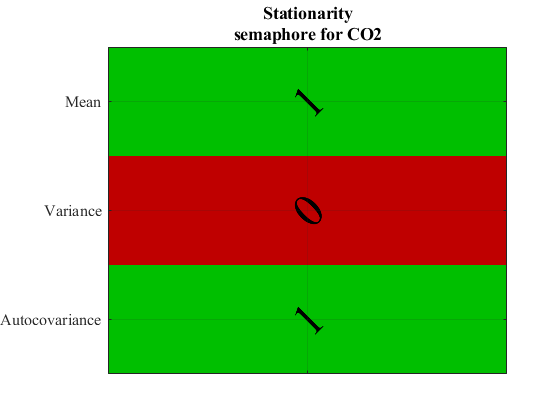

[~, mean_stat_flag1, var_stat_flag1, covar_stat_flag1] = isstationary(y_final);
figure(1)
matvisual([mean_stat_flag1; var_stat_flag1; covar_stat_flag1], 'annotation')
set(gca, 'FontName', 'Times New Roman')
title(['Stationarity' newline 'semaphore for CO2'])
xlabel([])
ylabel([])
set(gca, 'XTickLabel', [])
set(gca, 'YTickLabel', {'Mean', 'Variance', 'Autocovariance'})
colormap([0.75, 0, 0; 0, 0.75, 0])

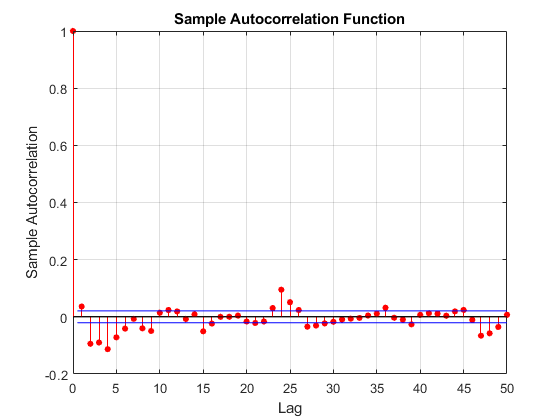

autocorr(y_final, 50)

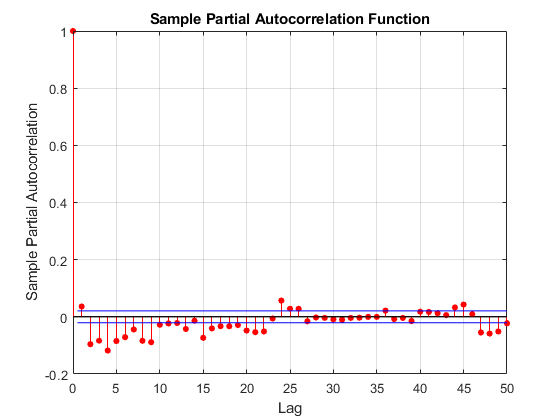

parcorr(y_final, 50)

% Variabile dipendente
y_final

y_final =     0.0502
   -0.0825
    0.0181
    0.0771
   -0.1703
    0.1429
   -0.1515
   -0.0663
    0.0393
    0.0113


% checking correlation between variables
A = sensor_data{:,:};
corrcoef(A)

ans =     1.0000    0.8753   -0.7920    0.6443    0.8890    0.0423    0.1083    0.1171
    0.8753    1.0000   -0.7932    0.7653    0.8751    0.2306   -0.0898    0.1703
   -0.7920   -0.7932    1.0000   -0.5286   -0.7984   -0.1267   -0.0624   -0.2125
    0.6443    0.7653   -0.5286    1.0000    0.5695    0.5609   -0.0266    0.6295
    0.8890    0.8751   -0.7984    0.5695    1.0000   -0.0475    0.1272    0.0446
    0.0423    0.2306   -0.1267    0.5609   -0.0475    1.0000   -0.5744    0.6588
    0.1083   -0.0898   -0.0624   -0.0266    0.1272   -0.5744    1.0000    0.1705
    0.1171    0.1703   -0.2125    0.6295    0.0446    0.6588    0.1705    1.0000



% Variabile indipendente
X = [sensor_data.("S2.NMHC"), sensor_data.("S3.NOx"), sensor_data.("S5.O3")];
Mdl0 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1:5,'Distribution','Gaussian');
EstMdl1 = estimate(Mdl0, y_final,'X',X,'Display','params')

 
    ARIMAX(2,0,5) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue   
                ___________    _____________    __________    ___________

    Constant      -0.091297       0.015151       -6.0256       1.6843e-09
    AR{1}           -1.1588       0.018418       -62.915                0
    AR{2}          -0.64008       0.019158        -33.41      9.8732e-245
    MA{1}            1.2761       0.020616        61.896                0
    MA{2}           0.71232       0.025654        27.766      1.1042e-169
    MA{3}         -0.062034       0.017063       -3.6356       0.00027732
    MA{4}            -0.121       0.015972       -7.5756       3.5758e-14
    MA{5}   

EstMdl1 =   arima with properties:

     Description: "ARIMAX(2,0,5) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 5
        Constant: -0.0912968
              AR: {-1.15878 -0.640078} at lags [1 2]
             SAR: {}
              MA: {1.27606 0.712323 -0.0620337 -0.120996 -0.050675} at lags [1 2 3 4 5]
             SMA: {}
     Seasonality: 0
            Beta: [0.000110397 -6.73762e-05 4.18983e-05]
        Variance: 0.00727842

summarize(EstMdl1)

 
   ARIMAX(2,0,5) Model (Gaussian Distribution)
 
    Effective Sample Size: 9236
    Number of Estimated Parameters: 12
    LogLikelihood: 9628.36
    AIC: -19232.7
    BIC: -19147.2
 
                   Value       StandardError    TStatistic      PValue   
                ___________    _____________    __________    ___________

    Constant      -0.091297       0.015151       -6.0256       1.6843e-09
    AR{1}           -1.1588       0.018418       -62.915                0
    AR{2}          -0.64008       0.019158        -33.41      9.8732e-245
    MA{1}            1.2761       0.020616        61.896                0
    MA{2}           0.71232       0.025654        27.766      1.1042e-169
    MA{3}         -0.062034       0.017


temp_AIC=0;
temp_model=arima('Constant',NaN,'ARLags',1:1,'D',0,'MALags',1:1,'Distribution','Gaussian');
for p = 1:4
    for q = 1:10
        
        model = arima('Constant',NaN,'ARLags',1:p,'D',0,'MALags',1:q,'Distribution','Gaussian');
        est_model = estimate(model, y_final,'X',X,'Display','params');
        if(temp_AIC> summarize(est_model).AIC)
        temp_model=summarize(est_model);
        end
        model_matrix(p,q) = est_model;
    end
end

 
    ARIMAX(1,0,1) Model (Gaussian Distribution):
 
                   Value       StandardError    TStatistic      PValue  
                ___________    _____________    __________    __________

    Constant      -0.020975       0.011327        -1.8518        0.06406
    AR{1}          0.024631        0.12861        0.19151        0.84813
    MA{1}          0.020971        0.12834        0.16341         0.8702
    Beta(1)      4.4388e-05     8.8293e-06         5.0274     4.9711e-07
    Beta(2)     -6.9006e-06     7.2886e-06       -0.94677        0.34376
    Beta(3)     -1.4656e-05     5.8778e-06        -2.4935        0.01265
    Variance      0.0082644     0.00010501         78.704              0

 
    ARIMAX(1,0,2) Model (Gaussi

summarize(model_matrix(3,6))

 
   ARIMAX(3,0,6) Model (Gaussian Distribution)
 
    Effective Sample Size: 9236
    Number of Estimated Parameters: 14
    LogLikelihood: 9867.06
    AIC: -19706.1
    BIC: -19606.3
 
                   Value       StandardError    TStatistic      PValue   
                ___________    _____________    __________    ___________

    Constant      -0.097242       0.015339       -6.3395        2.305e-10
    AR{1}           -1.2208       0.019618       -62.225                0
    AR{2}          -0.99012       0.025354       -39.052                0
    AR{3}          -0.46739       0.020085        -23.27      8.8433e-120
    MA{1}            1.3376       0.021586        61.968                0
    MA{2}            1.0951       0.030

summarize(model_matrix(3,6)).AIC

ans = -1.9706e+04

summarize(model_matrix(3,6)).Table

ans = 14×4 table
                   Value       StandardError    TStatistic      PValue   
                ___________    _____________    __________    ___________

    Constant      -0.097242       0.015339       -6.3395        2.305e-10
    AR{1}           -1.2208       0.019618       -62.225                0
    AR{2}          -0.99012       0.025354       -39.052                0
    AR{3}          -0.46739       0.020085        -23.27      8.8433e-120
    MA{1}            1.3376       0.021586        61.968                0
    MA{2}            1.0951       0.030943        35.392      2.2613e-274
    MA{3}           0.47055       0.028804        16.336       5.4405e-60
    MA{4}           -0.1091       0.019539  

## Residui

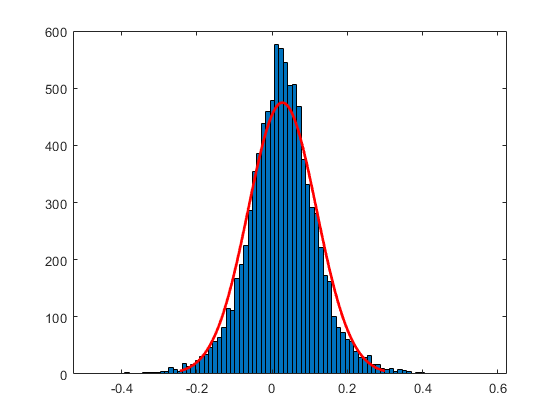

res = infer(model_matrix(3,6), y_final);
histfit(res)

archtest(res)

ans = logical
   1


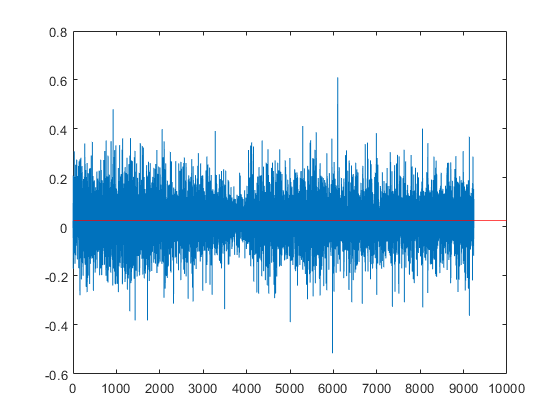

plot(res)
yline(mean(res), 'color', 'r')

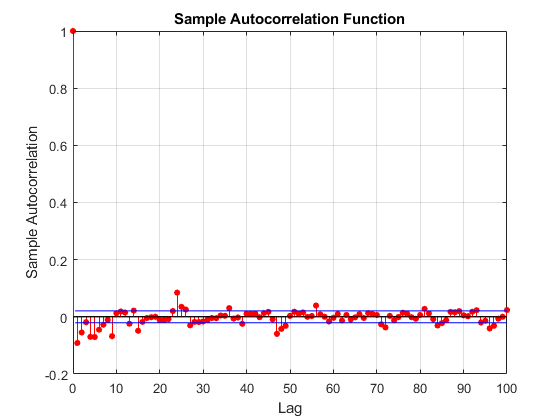

autocorr(res,100)

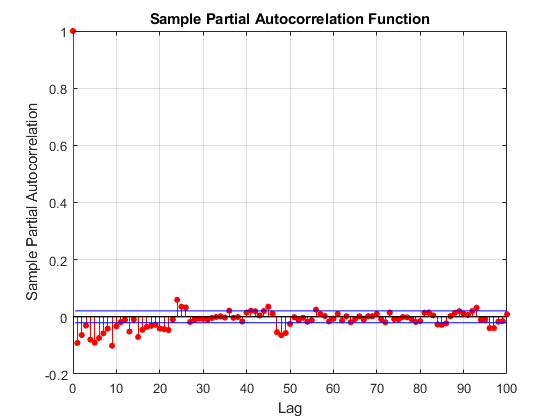

parcorr(res,100)

lbqtest(res)

ans = logical
   1


[~, mean_stat_flag1, var_stat_flag1, covar_stat_flag1] = isstationary(res);
figure(1)
matvisual([mean_stat_flag1; var_stat_flag1; covar_stat_flag1], 'annotation')
set(gca, 'FontName', 'Times New Roman')
title(['Stationarity' newline 'semaphore for CO2'])
xlabel([])
ylabel([])
set(gca, 'XTickLabel', [])
set(gca, 'YTickLabel', {'Mean', 'Variance', 'Autocovariance'})
colormap([0.75, 0, 0; 0, 0.75, 0])

jbtest(res)

ans = 1

mean(res)

ans = 0.0272

var(res)

ans = 0.0082

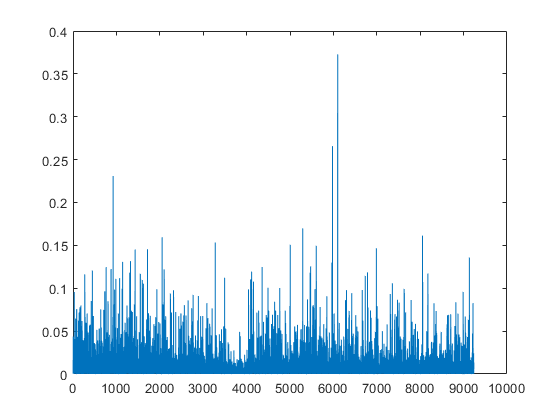

plot(res.^2)

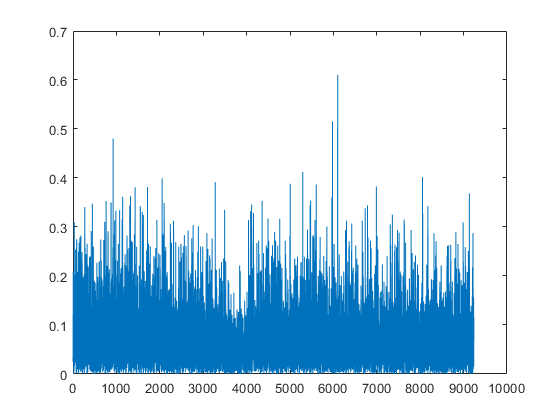

plot(abs(res))

sum(isoutlier(res))

ans = 171

res_table = array2table(res)

res_table = 9236×1 table
       res   
    _________

     0.024555
    -0.043266
     0.055505
     0.099879
     -0.17085
      0.20884
     -0.14984
    -0.024533
     0.070486
     0.029448
    -0.043038
      0.13631
     0.063554
    -0.074385
     0.070506
      0.15936


## Forecasting

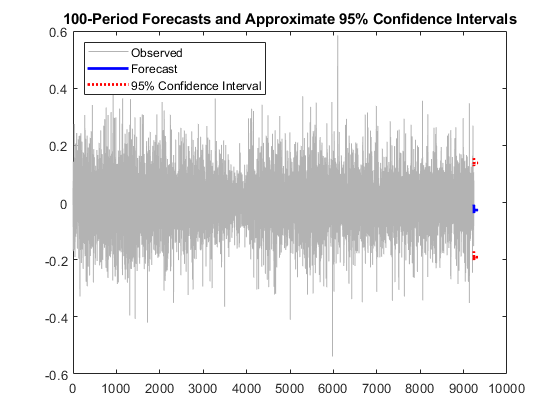


hf = 100;
[YF, YMSE] = forecast(model_matrix(3,6), hf, y_final);
figure
p1 = plot(y_final,'Color',[.7,.7,.7]);
hold on
Thf = (length(y_final) + 1):(length(y_final) + hf);
Thf = Thf';
p2 = plot(Thf,YF,'b','LineWidth',2);
p3 = plot(Thf,YF + 1.96*sqrt(YMSE),'r:',...
		'LineWidth',2);
plot(Thf,YF - 1.96*sqrt(YMSE),'r:','LineWidth',2);
legend([p1 p2 p3],'Observed','Forecast',...
		'95% Confidence Interval','Location','NorthWest');
title(['100-Period Forecasts and Approximate 95% '...
			'Confidence Intervals'])
hold off